# Preprocessing of Neuropixels recordings in the flight room

- Recording date: 2/6/2024

- Recording method: untethered recording in the flight room.

- Experiment setup: multiple bats (n=10) were flew in the flight room simultaneously. Two bats (14633 and 14662) were recorded for their neural activity.

- Target region of ephys recording: 14633 and 14662 was implanted with two probes respectively. For 14633, the probe 1 was targetting the dorsal/ventral hippocampus and the probe 2 was targetting the mEC. For 14662, the probe 1 was targetting the hippocampus and the mEC and the probe 2 was targetting the dorsal and ventral hippocampus.

- Feeder: feeder 1 and 2 was activated with a banana smoothie syringe.

## Recording information (Edit here)

rec_date = '240206'; % recording date
rec_type = 'untethered'; % recording type
exp_type = 'social_singleflavor_foraging'; % experiment type
data_dir = 'Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240206'; % parent directory for all recordings
cd(data_dir)

% Bat subjects
bname = {"14447","11827","29924","14406","14561","14633","14662","14531","71050","9776"}; % in order of serial number list
bname_ephys = {'14633','14662'}; % ephys bat

% reward
reward_list = {"banana","pear","grape","melon"};
reward_session = [1,1,0,0];
save('exp_info.mat','rec_date','rec_type','exp_type','bname','bname_ephys','reward_list','reward_session')

### Directory to ouput the results

% output directory
res_dir_path     =   fullfile(data_dir,'analysis');
if isempty(dir(res_dir_path))
    mkdir(res_dir_path)
end
% Figure
fig_dir_path    =   fullfile(res_dir_path,'figure');
if isempty(dir(fig_dir_path))
    mkdir(fig_dir_path)
end

## Preprocessing of Neuropixels data

### Extracting LFP, spikeband, and other data types    

trodes_path = 'C:\Users\Tatsumi\Documents\Trodes\Trodes_2-5-0_Windows64'; % trodes 2.5.0
exportAllTrodesRecordingsAllBats(data_dir,trodes_path,'isTethered',0); % extract LFP, spikeband, kilosort dat, etc. from the raw data for all bats

### Run kilosort

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240206\ephys\20240206_103805.rec\14633\20240206_103805_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time   5s. Loading raw data and applying filters... 
Time 142s. Finished preprocessing 399 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8     0     8    16    24

        1302

0.28 sec, 1 batches, 4878 spikes 
27.10 sec, 101 batches, 481121 spikes 
55.31 sec, 201 batches, 878958 spikes 
86.36 sec, 301 batches, 1225709 spikes 
119.69 sec, 399 batches, 1620219 spikes 


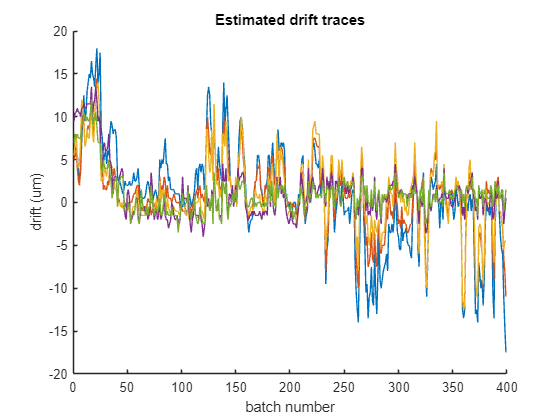

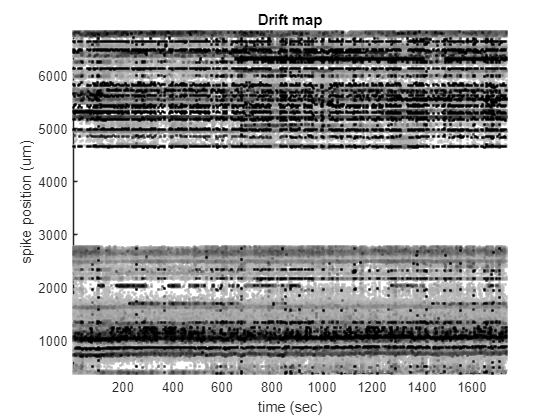

time 276.89, Shifted up/down 399 batches. 
0.35 sec, 1 batches, 6862 spikes 
32.01 sec, 101 batches, 887127 spikes 
63.87 sec, 201 batches, 1771012 spikes 
95.88 sec, 301 batches, 2599454 spikes 
127.09 sec, 399 batches, 3462177 spikes 
time 0.00, GROUP 1/326, units 0 
time 4.76, GROUP 6/326, units 15 
time 13.14, GROUP 11/326, units 41 
time 20.69, GROUP 16/326, units 60 
time 30.19, GROUP 21/326, units 82 
time 36.00, GROUP 26/326, units 100 
time 38.47, GROUP 31/326, units 109 
time 40.44, GROUP 36/326, units 116 
time 42.82, GROUP 41/326, units 125 
time 50.12, GROUP 46/326, units 147 
time 53.59, GROUP 51/326, units 157 
time 56.41, GROUP 56/326, units 165 
time 61.43, GROUP 61/326, units 177 
time 64.64, GROUP 66/326, units 186 
time 64.64, GROUP 71/326, units 186 
time 64.65, GROUP 76/326, units 186 
time 64.65, GROUP 81/326, units 186 
time 64.65, GROUP 86/326, units 186 
time 64.65, GROUP 91/326, units 186 
time 64.65, GROUP 96/326, units 186 
time 64.65, GROUP 101/326, units 

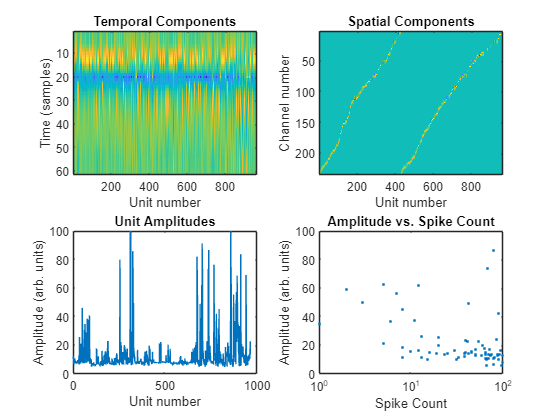

time 0.00, GROUP 1/326, units 0 
time 2.84, GROUP 6/326, units 16 
time 8.28, GROUP 11/326, units 46 
time 15.29, GROUP 16/326, units 69 
time 23.12, GROUP 21/326, units 95 
time 28.93, GROUP 26/326, units 112 
time 32.13, GROUP 31/326, units 125 
time 35.79, GROUP 36/326, units 142 
time 42.33, GROUP 41/326, units 173 
time 46.91, GROUP 46/326, units 191 
time 50.93, GROUP 51/326, units 208 
time 54.60, GROUP 56/326, units 223 
time 65.19, GROUP 61/326, units 258 
time 65.35, GROUP 66/326, units 259 
time 65.36, GROUP 71/326, units 259 
time 65.36, GROUP 76/326, units 259 
time 65.36, GROUP 81/326, units 259 
time 65.36, GROUP 86/326, units 259 
time 65.37, GROUP 91/326, units 259 
time 65.37, GROUP 96/326, units 259 
time 65.37, GROUP 101/326, units 259 
time 65.38, GROUP 106/326, units 259 
time 65.38, GROUP 111/326, units 259 
time 65.38, GROUP 116/326, units 259 
time 65.38, GROUP 121/326, units 259 
time 65.39, GROUP 126/326, units 259 
time 65.39, GROUP 131/326, units 259 
time 

ans = 137

initialized spike counts
merged 58 into 57 
merged 89 into 86 
merged 255 into 259 
merged 589 into 592 
merged 549 into 536 
merged 42 into 48 
merged 623 into 627 
merged 83 into 84 
merged 619 into 627 
merged 271 into 279 
merged 671 into 677 
merged 450 into 453 
merged 567 into 558 
merged 392 into 393 
merged 558 into 574 
merged 204 into 195 
merged 436 into 445 
merged 209 into 212 
merged 174 into 172 
merged 74 into 78 
merged 454 into 446 
merged 562 into 557 
merged 235 into 239 
merged 39 into 47 


ans = 121

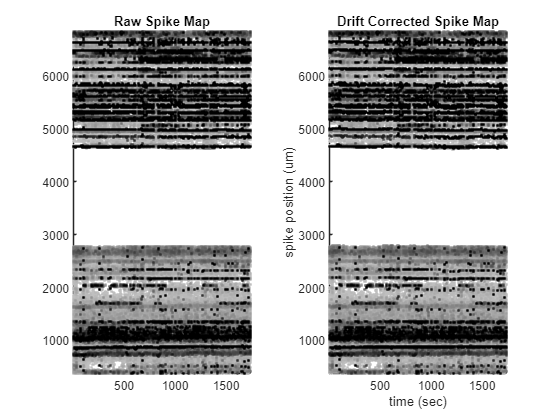

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [235×1 double]
                 yc: [235×1 double]
            xcoords: [235×1 double]
            ycoords: [235×1 double]
               Wrot: [235×235 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×235 gpuArray]
               dist: [10×2114 single]
              iorig: [399×1 double]
             dshift: [399×5 double]
                st0: [1620219×6 double]
                  F: [1302×20×399 double]
                 F0: [1302×20 gpuArray]
                F0m: [1302×20 gpuArray]
               ycup: [360 360 360 360 360 370 370 370 370 370 380 380 380 390 390 390 390 390 400 400 400 400 400 410 410 410 410 410 420 420 420 430 430 430 430 430 440 440 440 440 440 450 450 450 450 450 460 460 460 470 470 470 470 … ] (1×2114 double)
               xcup: [-24 -16 -8 0 8 -24 -16 -8 0 8 -24 -16 -8 -24 -16 -8 0 8 -24 -16 -8 

% 14633
path_to_rec_dir = dir(fullfile(data_dir,'ephys','*.rec','14633','*merged.rec')); path_to_rec_dir = path_to_rec_dir.folder;
chanmap_file = dir(fullfile(data_dir,'ephys','*.rec','14633','*.kilosort','channelmap_probe*'));
for probeNum = 1:length(chanmap_file)

Looking for data inside Z:\users\Tatsumi\data\MultiReward\multibat\flightroom\240206\ephys\20240206_103805.rec\14633\20240206_103805_merged.kilosort 


errString = 'kilosort repo not found, or inaccessible.'

Time   0s. Computing whitening matrix.. 
Getting channel whitening matrix... 
Channel-whitening matrix computed. 
Time   3s. Loading raw data and applying filters... 
Time  91s. Finished preprocessing 399 batches. 
vertical pitch size is 20 
horizontal pitch size is 16 
   -24   -16    -8

   658

0.13 sec, 1 batches, 7088 spikes 
13.97 sec, 101 batches, 600494 spikes 
28.77 sec, 201 batches, 1284650 spikes 
44.98 sec, 301 batches, 1986601 spikes 
62.53 sec, 399 batches, 2711894 spikes 


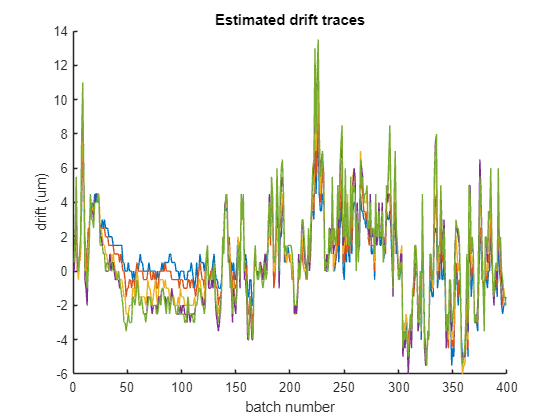

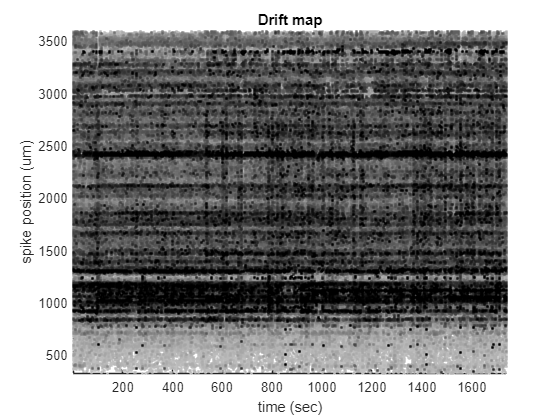

time 156.46, Shifted up/down 399 batches. 
0.16 sec, 1 batches, 10000 spikes 
15.89 sec, 101 batches, 989508 spikes 
31.70 sec, 201 batches, 1977577 spikes 
47.68 sec, 301 batches, 2959786 spikes 
63.17 sec, 399 batches, 3907653 spikes 
time 0.00, GROUP 1/83, units 0 
time 3.58, GROUP 6/83, units 23 
time 8.90, GROUP 11/83, units 55 
time 21.09, GROUP 16/83, units 100 
time 49.53, GROUP 21/83, units 185 
time 69.27, GROUP 26/83, units 233 
time 96.90, GROUP 31/83, units 304 
time 117.84, GROUP 36/83, units 368 
time 140.78, GROUP 41/83, units 431 
time 155.49, GROUP 46/83, units 474 
time 167.36, GROUP 51/83, units 513 
time 181.56, GROUP 56/83, units 554 
time 201.79, GROUP 61/83, units 614 
time 213.48, GROUP 66/83, units 657 
time 223.49, GROUP 71/83, units 693 
time 238.71, GROUP 76/83, units 752 
time 249.31, GROUP 81/83, units 806 
Elapsed time is 252.739713 seconds.
Time 255s. Final spike extraction ...
255.46 sec, 1 / 399 batches, 821 units, nspks: 14901, mu: 11.9111, nst0: 149

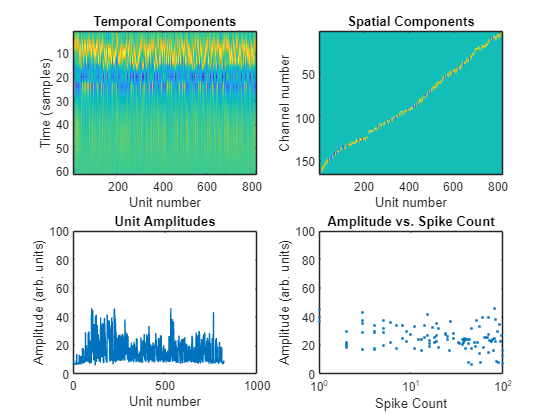

time 0.00, GROUP 1/83, units 0 
time 2.88, GROUP 6/83, units 16 
time 7.56, GROUP 11/83, units 38 
time 15.08, GROUP 16/83, units 62 
time 38.78, GROUP 21/83, units 120 
time 49.85, GROUP 26/83, units 151 
time 74.75, GROUP 31/83, units 219 
time 94.55, GROUP 36/83, units 271 
time 109.81, GROUP 41/83, units 314 
time 121.29, GROUP 46/83, units 343 
time 131.80, GROUP 51/83, units 371 
time 149.36, GROUP 56/83, units 419 
time 165.83, GROUP 61/83, units 465 
time 177.08, GROUP 66/83, units 503 
time 187.66, GROUP 71/83, units 540 
time 204.75, GROUP 76/83, units 587 
time 213.09, GROUP 81/83, units 617 
Elapsed time is 216.142196 seconds.


ans = 225

initialized spike counts
merged 208 into 192 
merged 386 into 380 
merged 450 into 455 
merged 462 into 458 
merged 410 into 409 
merged 135 into 123 
merged 385 into 380 
merged 197 into 205 
merged 584 into 582 
merged 209 into 192 
merged 403 into 404 
merged 179 into 184 
merged 116 into 121 
merged 65 into 64 
merged 524 into 520 
merged 347 into 344 
merged 422 into 416 
merged 437 into 427 
merged 250 into 243 
merged 111 into 109 
merged 206 into 211 
merged 113 into 109 
merged 315 into 309 
merged 487 into 496 
merged 200 into 205 
merged 443 into 455 
merged 169 into 185 
merged 217 into 196 
merged 227 into 214 
merged 578 into 570 
merged 447 into 430 
merged 619 into 608 
merged 336 into 344 
merged 602 into 609 
merged 283 into 290 
merged 472 into 477 
merged 546 into 548 
merged 383 into 398 
merged 232 into 245 
merged 471 into 476 
merged 281 into 280 
merged 436 into 424 
merged 276 into 266 
merged 332 into 326 
merged 466 into 456 
merged 88 into 94 
merged 552 in

ans = 188

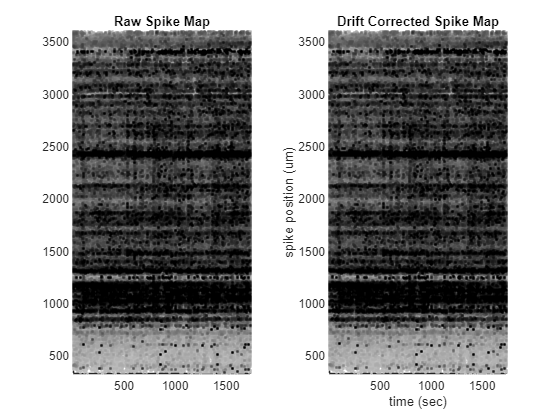

ans = struct with fields:
                ops: [1×1 struct]
                 xc: [165×1 double]
                 yc: [165×1 double]
            xcoords: [165×1 double]
            ycoords: [165×1 double]
               Wrot: [165×165 double]
               temp: [1×1 struct]
              wTEMP: [61×6 single]
               wPCA: [61×6 single]
                 iC: [16×165 gpuArray]
               dist: [10×987 single]
              iorig: [399×1 double]
             dshift: [399×5 double]
                st0: [2711894×6 double]
                  F: [658×20×399 double]
                 F0: [658×20 gpuArray]
                F0m: [658×20 gpuArray]
               ycup: [320 320 320 330 330 330 340 340 340 350 350 350 360 360 360 370 370 370 380 380 380 390 390 390 400 400 400 410 410 410 420 420 420 430 430 430 440 440 440 450 450 450 460 460 460 470 470 470 480 480 480 490 490 … ] (1×987 double)
               xcup: [-24 -16 -8 -24 -16 -8 -24 -16 -8 -24 -16 -8 -24 -16 -8 -24 -16 -8 -24 -1

    chanmap = load(fullfile(chanmap_file(probeNum).folder,chanmap_file(probeNum).name));

    numChannels = length(chanmap.chanMap);

kilosort finished!


    runKilosort3(path_to_rec_dir,'probeNum',probeNum,'numChannels',numChannels)
end
disp('kilosort finished!')

## Preprocessing of cdp data

### Data directory

% cdp
cdp_dir = dir(fullfile(data_dir,'cdp','*cdp*.txt')); cdp_path = fullfile(cdp_dir.folder,cdp_dir.name);
% serial number
serial_dir = dir(fullfile(data_dir,'*Serial_numbers*')); serial_path = fullfile(serial_dir.folder,serial_dir.name);
% cortex
cortex_dir  =   dir(fullfile(data_dir,'cortex','*c3d'));
cortex_file =   fullfile(cortex_dir.folder,cortex_dir.name);
% reward
reward_dir  =   dir(fullfile(data_dir,'reward','*.mat'));

% experiment info
load('exp_info.mat')
n_session = size(reward_session,1);
reward_summary = cell(n_session,4);
for i = 1:n_session
    for fd = 1:4
        fl = reward_session(i,fd);
        if fl ~= 0
            reward_summary{i,fd} = reward_list{fl};
        end
    end
end
reward_summary

reward_summary = 1×4 cell array
    {'banana'}    {'banana'}    {0×0 double}    {0×0 double}


### Preprocess the cdp data

Extract the tag data from the raw cdp data by the *ExtractCdp* function. *sync_data(:,8)* is the timestamps interpolated based on the pseudo-Fibonacci TTLs. In this time vector, t=0 is the timing of the 1st pulse of the pseudo-Fibonacci TTLs. Make sure that this time vector will be shifted for 1.05 sec to set t=0 as the 1st pulse of the 3-sec TTLs.

                 Fs: 100
             tag_SN: [10×1 double]
            sync_SN: 17040920
               sync: 1
      sync_duration: 28.5297
       sync_samples: 171171
       tag_duration: [28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5304 28.5306 28.5304]
        tag_samples: [170306 170252 170354 170276 170291 154435 170314 162235 170214 170279]
    tag_ac_duration: [28.5305 28.5304 28.5303 28.5304 28.5304 28.5304 28.5305 28.5305 28.5304 28.5304]
     tag_ac_samples: [170289 170309 172164 171475 172088 155443 172799 163493 172589 171176]
               tags: 10

All TTLs were detected, alignment OK
Sync: Fs (network time VS interpolated): 100Hz VS 98.12 Hz
Pos Tag1: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag2: Fs (network time VS interpolated): 99.46 Hz VS 97.6 Hz


Pos Tag3: Fs (network time VS interpolated): 99.52 Hz VS 97.65 Hz


Pos Tag4: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Pos Tag5: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz


Pos Tag6: Fs (network time VS interpolated): 90.22 Hz VS 88.53 Hz


Pos Tag7: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz


Pos Tag8: Fs (network time VS interpolated): 94.77 Hz VS 93 Hz


Pos Tag9: Fs (network time VS interpolated): 99.43 Hz VS 97.57 Hz


Pos Tag10: Fs (network time VS interpolated): 99.47 Hz VS 97.61 Hz


Acc Tag1: Fs (network time VS interpolated): 99.48 Hz VS 97.62 Hz
Acc Tag2: Fs (network time VS interpolated): 99.49 Hz VS 97.63 Hz
Acc Tag3: Fs (network time VS interpolated): 100.6 Hz VS 98.69 Hz
Acc Tag4: Fs (network time VS interpolated): 100.2 Hz VS 98.3 Hz
Acc Tag5: Fs (network time VS interpolated): 100.5 Hz VS 98.65 Hz
Acc Tag6: Fs (network time VS interpolated): 90.8 Hz VS 89.11 Hz
Acc Tag7: Fs (network time VS interpolated): 100.9 Hz VS 99.06 Hz
Acc Tag8: Fs (network time VS interpolated): 95.51 Hz VS 93.72 Hz
Acc Tag9: Fs (network time VS interpolated): 100.8 Hz VS 98.94 Hz
Acc Tag10: Fs (network time VS interpolated): 100 Hz VS 98.13 Hz


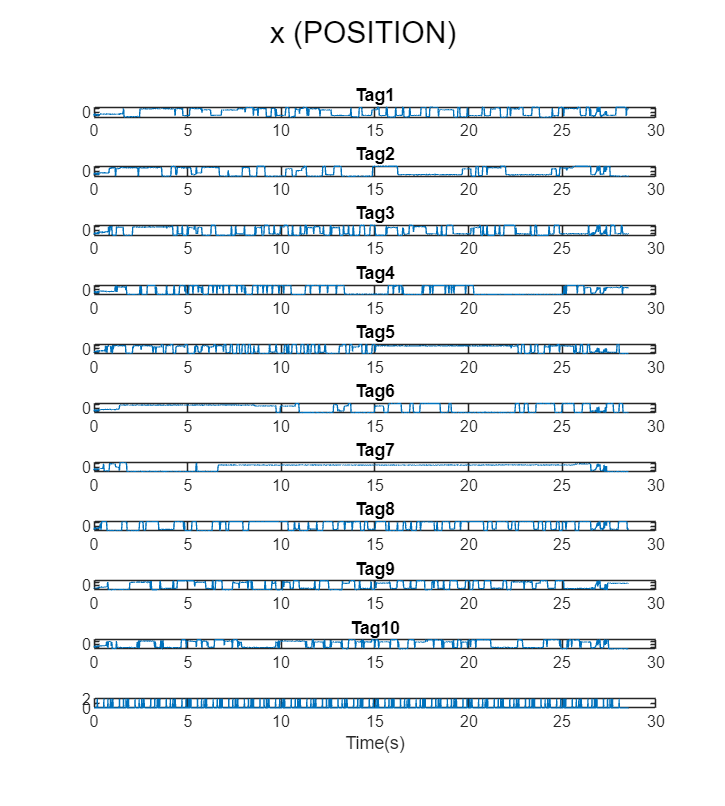

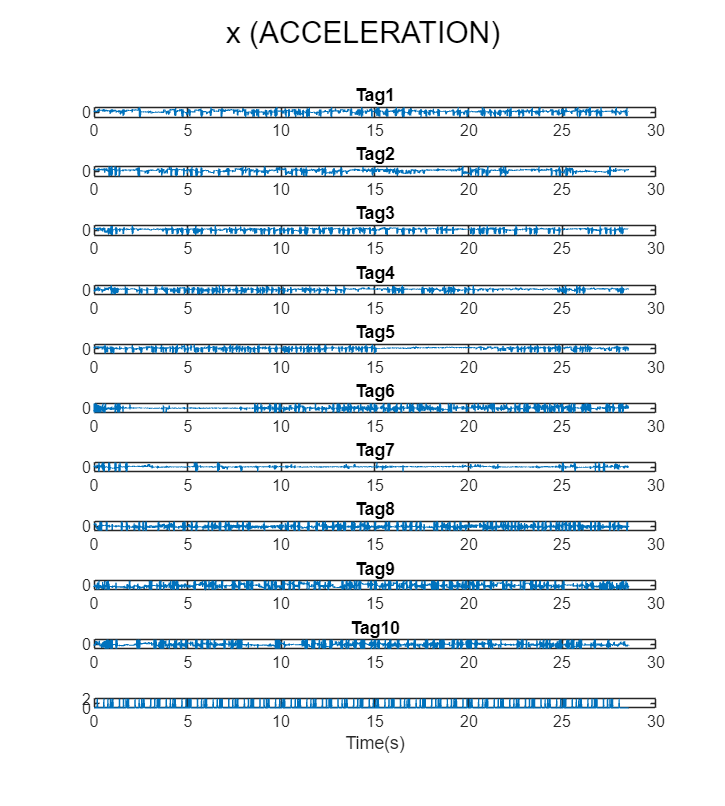

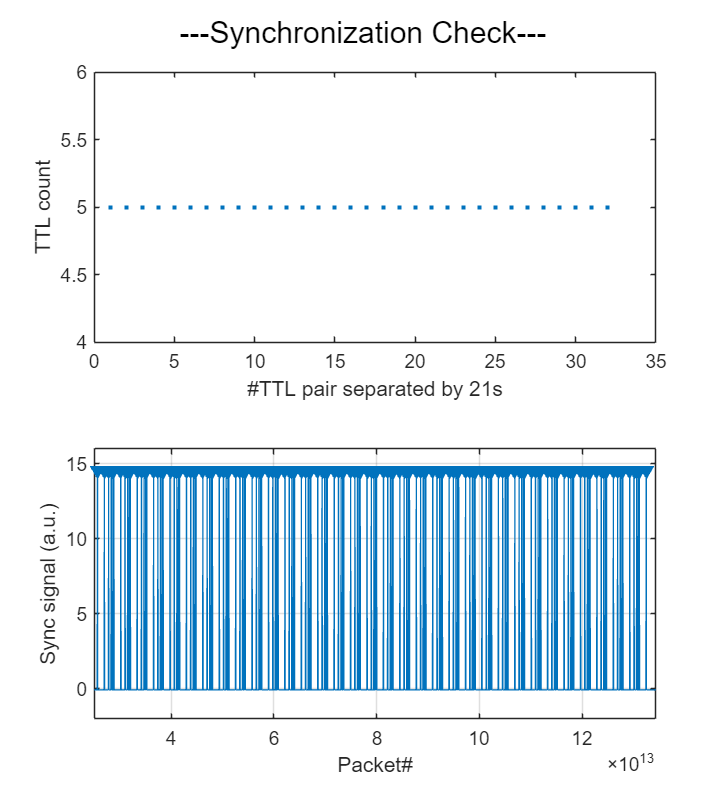

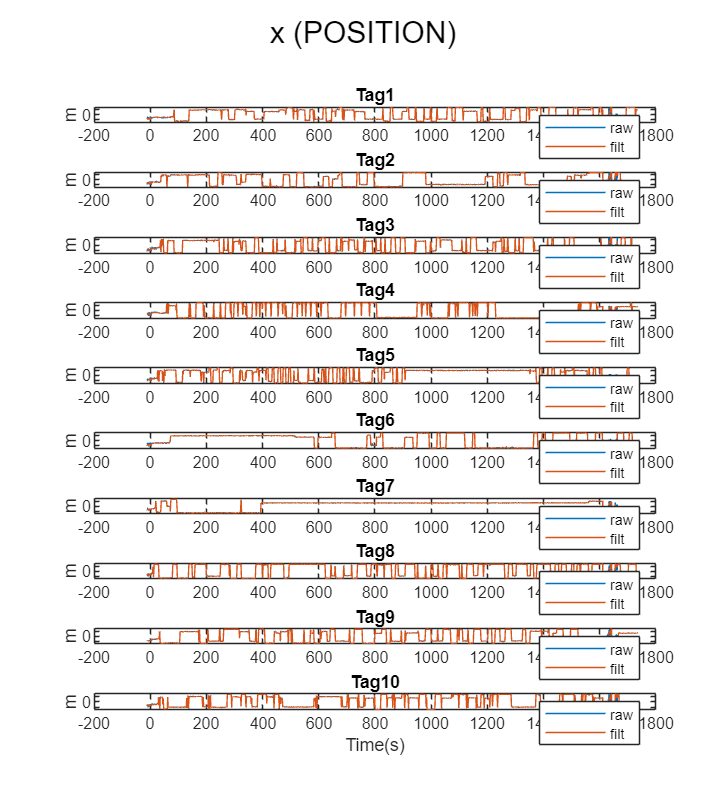

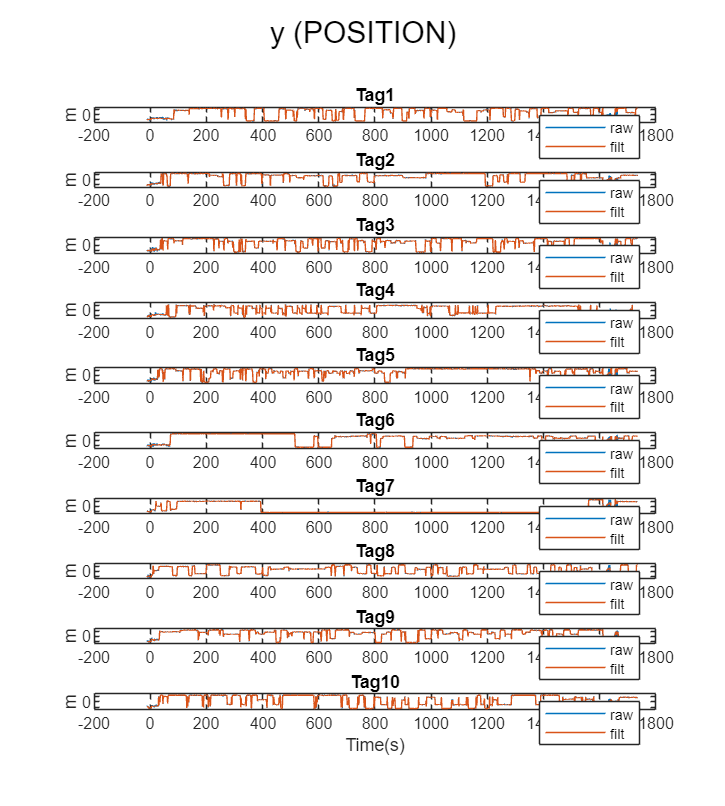

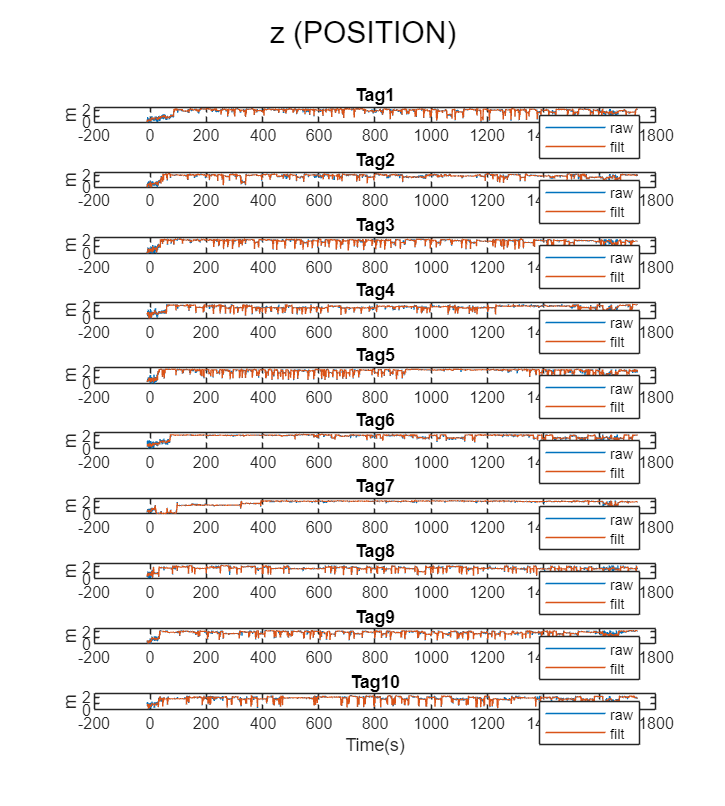

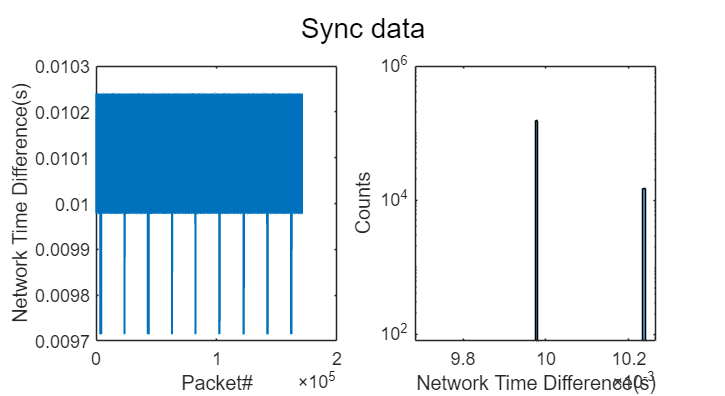

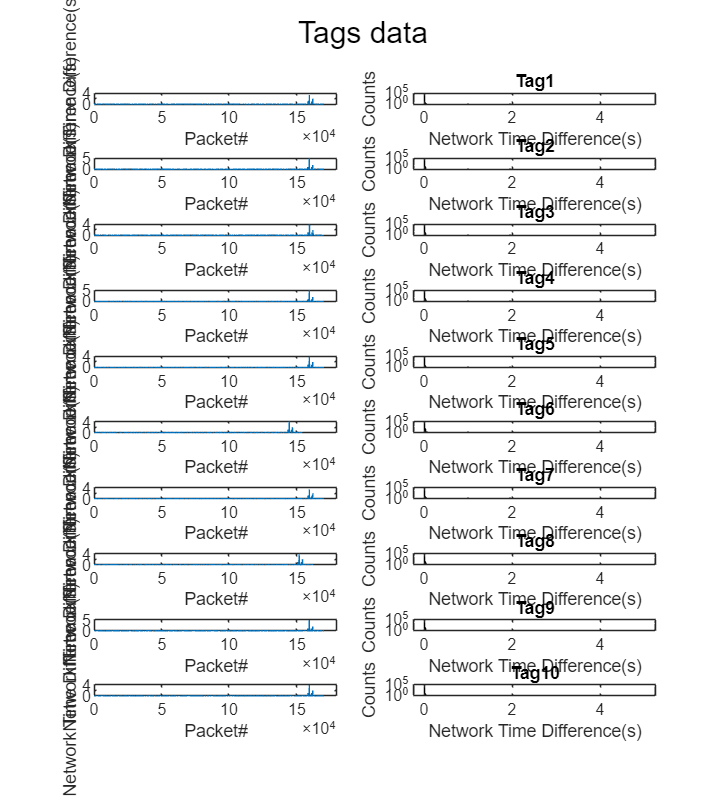

% Preprocess raw cdp data
cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*')); % raw cdp data
serial_number   =   load(serial_path); serial_number   =   serial_number'; % serial number of tags
if isempty(cdp_extracted)
    cd(cdp_dir.folder)
    ExtractCdp_AF_TY_v2('cdp',res_dir_path,'Include',serial_number) % Extract cdp data keeping the tag order
    cd(data_dir)
    % Load data
    cdp_extracted   =   dir(fullfile(res_dir_path,'extracted*cdp*'));
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
elseif length(cdp_extracted) == 1
    disp('Extracted data are found in the directory.')
    load(fullfile(cdp_extracted.folder,cdp_extracted.name))
else
    error('Multiple files with the specified name were found. Check the file name.')
end

Output file is *extracted_YYMMDD_cdp_*.mat* under the "analysis" directory.

### Extract behavior data

The *Process_extracted_cdp* function extract behavioral features from the preprocessed data. The output is *Extracted_Behavior_YYMMDD.mat* under the "Ext_Behavior_YYMMDD_HHMM.mat" directory.

The variable *t* in the output file is the time vector for global time. The global time is set so that t=0 is the timing of the 1st 3-sec TTLs.

...Processing Ciholas Data...


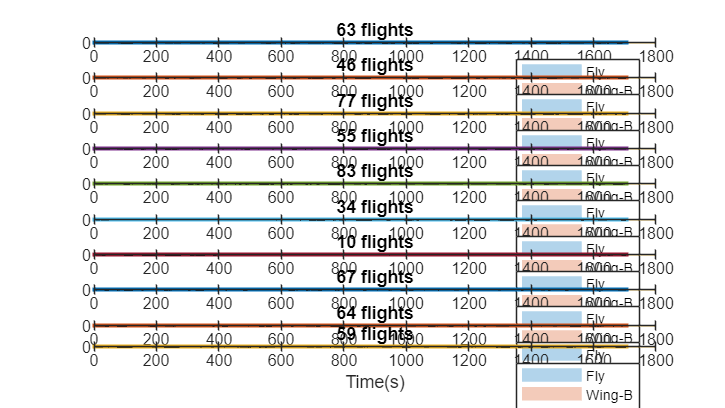

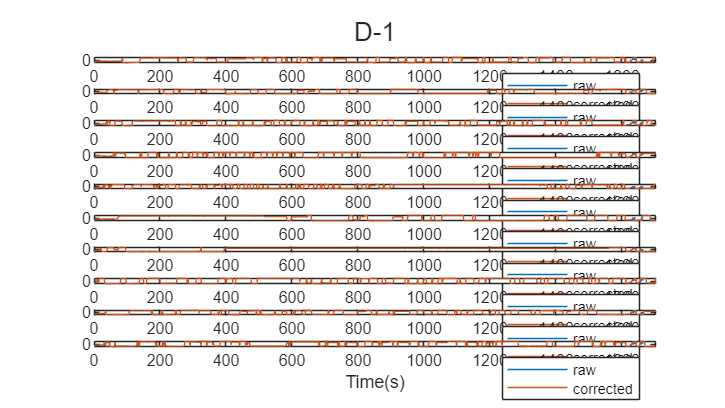

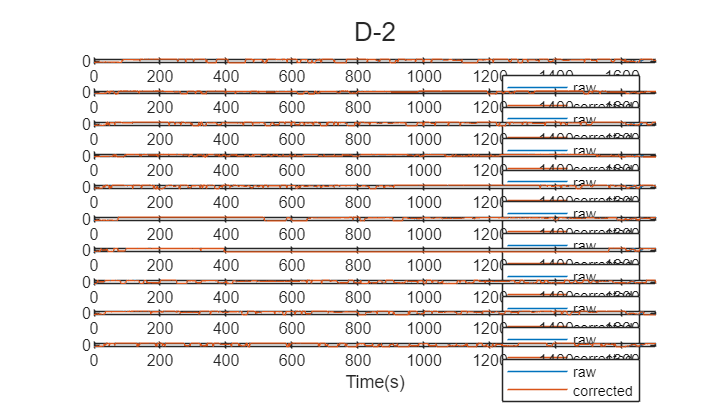

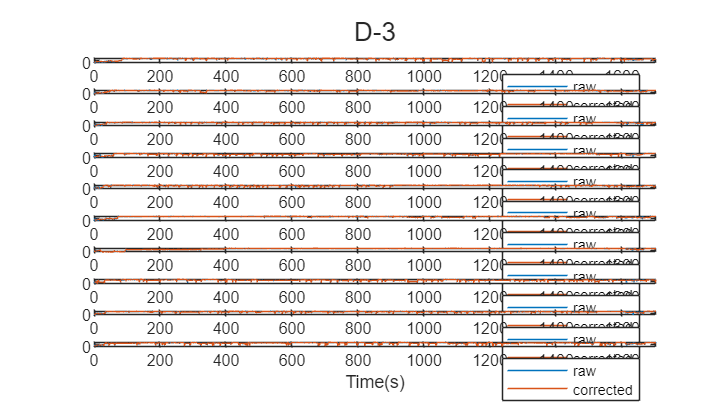

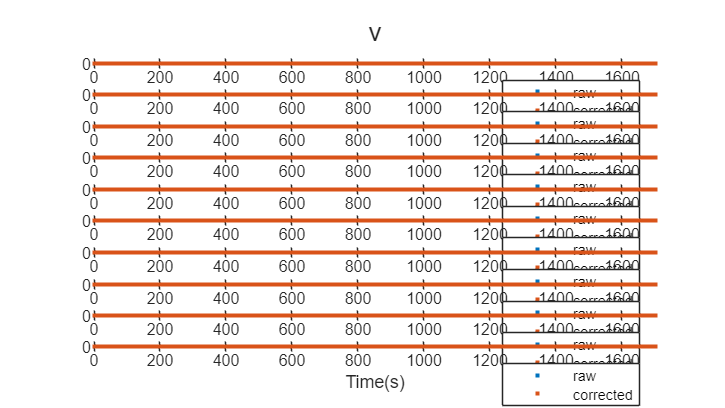

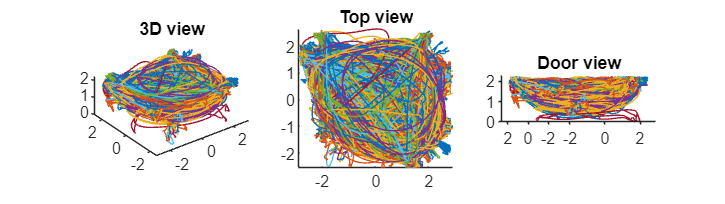

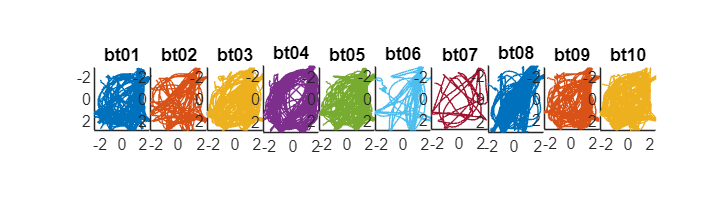

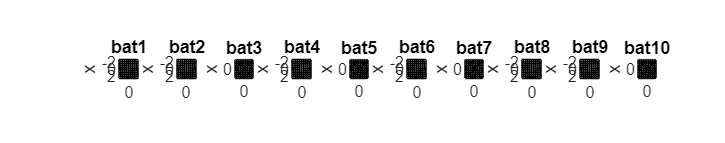

% Extract behaviors
beh_dir             =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
if isempty(beh_dir)
    cd(res_dir_path)
    Process_extracted_cdp_TY_v0(res_dir_path) % Extract behavioral features
    cd(data_dir)
    % Load data
    beh_dir         =   dir(fullfile(res_dir_path,'Ext_Behavior*','Extracted_Behavior*'));
    load(fullfile(beh_dir.folder,beh_dir.name))
elseif length(cdp_extracted) == 1
    disp('Behavior data are found in the directory.')
    load(fullfile(beh_dir.folder,beh_dir.name))
    disp('Behavior data are loaded.')
else
    error('Multiple files were contained in the directory. Check the file name.')
end

### Extract feeder data

The information related to reward provision is stored in the MATLAB files in the reward directory. These files contain the timings of reward provision, the identity of the bat who landed on feeders, the identity of feeders, etc.

#### Extracting sync signals

Extract the sync and reward information from the c3d file and save them into a MATLAB file.

% Extract synchronization and reward signals from c3d file
analog_dir = dir(fullfile(res_dir_path,'analog_signal.mat'));
if isempty(analog_dir)
    [~,~,AnalogSignals,AnalogFrameRate,~,~,~] = readC3D_analog(cortex_file); % read C3D data. Column 1 = reward, Column 2 = TTL, Column 3 = CDP server
elseif length(analog_dir)==1
    disp('Analog signal data are found.')
    load(fullfile(res_dir_path,'analog_signal.mat'),'AnalogSignals','AnalogFrameRate')
else
    error('Multiple files were contained in the directory. Check the file name.')
end
AnalogSignals = process_analog_signals(AnalogSignals,AnalogFrameRate);